global W umax %fgv miatt

T1=10;T2=4;T3=1; Ts=2; %[sec]
A=2; umax=5;

%b 
%Ts=3;
%tulloves, tul sokaig tartja az umaxot

%c
%Ts=1
%nem az elso beavatkozo jel a max

%d
Ts=fsolve('my_db',1);

ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


%elvileg igy kene tokeletes legyen

W= tf(A, conv(conv([T1 1],[T2 1]),[T3 1]));

Diszkret atvitel

D=c2d(W, Ts, 'zoh'); %vezeto nullat kapunk, kezelni kell
B=D.Numerator{1};
find(B~=0)

ans =      2     3     4


nem_null = find(B~=0);
B=B(nem_null(1):end)

B =     0.0205    0.0498    0.0070


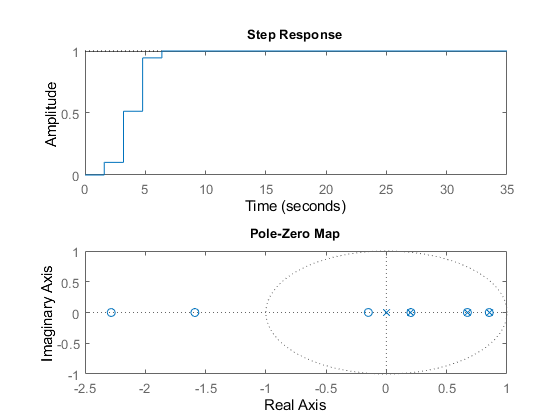

A = D.Denominator{1};
l0 = umax/A(1);
l1= 1/sum(B)-l0;
L= [l0 l1];
c_num=conv(L,A);
c_den= [1 -conv(L, B)];
Dc=tf(c_num, c_den,Ts);
D0=D*Dc;
Dyr= feedback(D0, 1,-1);
figure(1);
subplot(211); step(Dyr);
subplot(212); pzmap(Dyr);

%harmadfoku volt
%4 lepes alatt beallt 1-re
% 4 polus, mind a 4 az origoban
% mivel nevezo Z^4

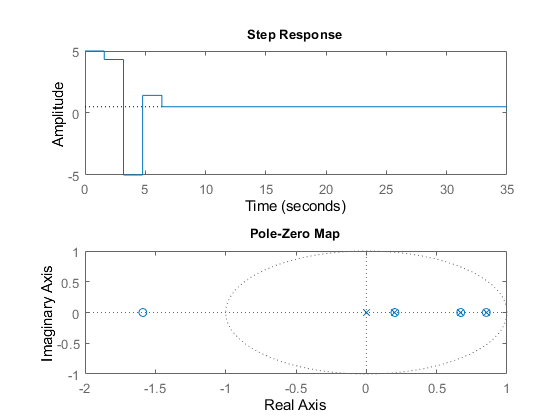

Dur=feedback(Dc,D,-1);
figure(2);
subplot(211); step(Dur);
subplot(212); pzmap(Dur);

Ts=fsolve('my_db',1);

ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4


ans =      2     3     4



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


my_db(Ts) %lehetoleg nulla kozeli legyen a koltseg 

ans =      2     3     4


ans = 5.2298e-12

sys=ss(W)

sys =
 
  A = 
          x1     x2     x3
   x1  -1.35  -0.75   -0.2
   x2    0.5      0      0
   x3      0   0.25      0
 
  B = 
        u1
   x1  0.5
   x2    0
   x3    0
 
  C = 
        x1   x2   x3
   y1    0    0  0.8
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



%mas kanonikus format alkothat, mint mi papiron
eig(sys.a)

ans =    -1.0000
   -0.2500
   -0.1000
